# Interpolazione con Chebyshev

Polinomio di Chebyshev di grado $n$

    $T_n \left(x\right)=\cos \left(n\;\varphi \right)$ dove $x=\cos \left(\varphi \right)$

I Nodi di Chebyshev sono gli zeri ddel polinomio di Chebyshev $T_n \left(x\right)$

Si arriva a dimostrare facendo le dovute sostituzioni che gli n nodi

$\varphi_k =\frac{\pi }{2n}+\frac{k}{n}\pi$ per $k=0\;\ldotp \ldotp \ldotp n-1$

Dato che per l'interpolazione sono necessari $n+1$ nodi, basta sostituire $n+1$ a $n$


$$\varphi_{k} = \frac{\pi}{2(n+1)} + \frac{k \pi}{n+1} = \frac{(2k+1)}{2(n+1)}\pi\ \ con \ \ k=0\ ...\ n$$


per interpolare una funzione di grado n ho bisogno di $n+1$ nodi

per ricavare sufficienti nodi di Chebyshev è necessario trovare le radici di $T_{n+1} \left(x\right)$

% chebNodes = @(k, grad) ...
%     cos( ...
%         (2*k + 1) * pi / ...
%         (2*grad + 2) ...
%     );

## Esempio n = 5

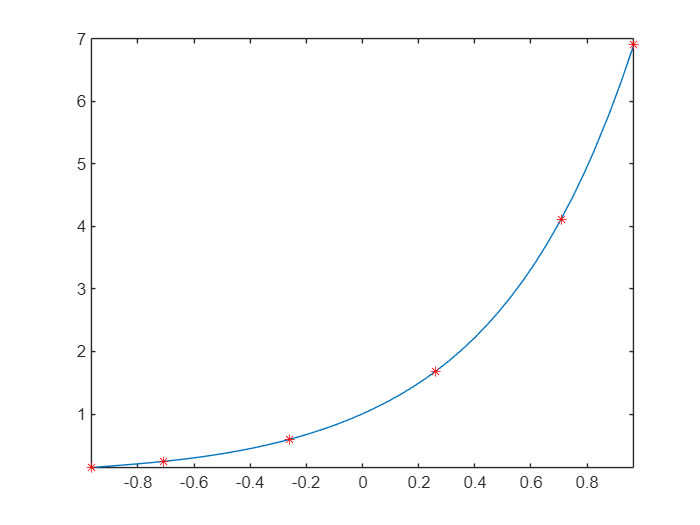

% cerchiamo un polinomio di interpolazione di grado 5
grado = 5;

chebNodes = @(k, grad) ...
    cos( ...
        (2*k + 1) * pi / ...
        (2*grad + 2) ...
    );

indici = 0 : grado;
nodi   = chebNodes(indici, grado);

funz = @(x) exp(2*x);
ordinate = funz(nodi);

% dopo aver ricavato le ordinate della funzione nei nodi calcolati
% si procede ad utilizzare polyfit e polyval (o poly2sym in base a cosa serve)

coeff = polyfit(nodi, ordinate, grado);
p     = poly2sym(coeff);

fplot(p, [min(nodi), max(nodi)])
hold on, plot(nodi, ordinate, 'r*'), hold off